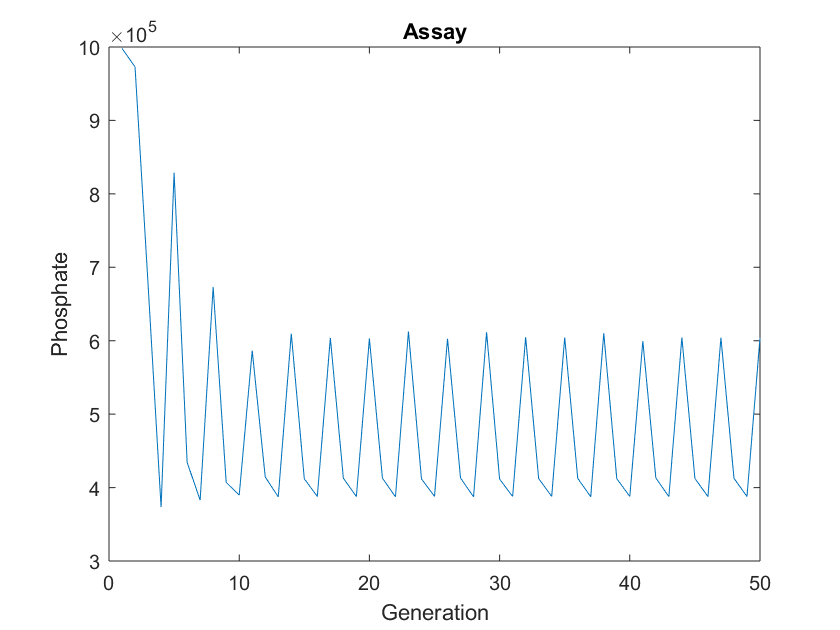

%%% Initialize
Population=1;
InitialPhosphate=1000000;
InitialEnergy=1000000;
Gen=50;
PopulationData=zeros(1,Gen);
PhosphateData=zeros(1,Gen);

% Generating Time Variance
Time=100.*ones(1,Gen);
for it=1:3:Gen
    Time(it)=Time(it)*1.5;
end

%%% Start Simulation
for Generation=1:1:Gen
    Phosphate=InitialPhosphate;
    Energy=InitialEnergy;
    % De-novo spawns
    Population=Population+1;
    
    for t=0:1:Time(Generation)
        Food=Energy/(Population+1);
        Energy=Energy-Population/33;
        Phosphate=Phosphate-Population*Phosphate/InitialPhosphate/33;
        % Prevent negative food
        if Phosphate < 0
            Phosphate =0;
        end
        if Energy < 0
            Energy =0;
        end
        
        
        % Growth/Death
        if 1 < Food
            Population=Population*1.05;
        else
            Population=round(Population*Food*1.05);
        end
        
    end
    % Data Collection
    PopulationData(Generation)=Population;
    PhosphateData(Generation)=Phosphate;
    
    % Kill 90%
    n=0;
    for i=1:1:Population
        if rand(1) < 0.1
            n=n+1;
        end
    end
    Population=n;
end
% Display
g=1:1:Gen;
plot(g,PhosphateData)
xlabel('Generation')
ylabel('Phosphate')
title('Assay')

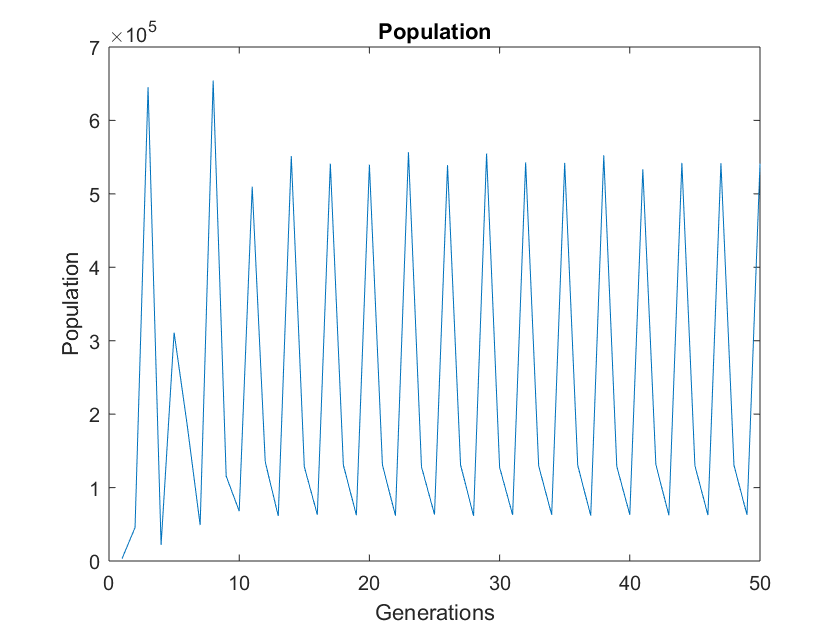

plot(g,PopulationData)
xlabel('Generations')
ylabel('Population')
title('Population')